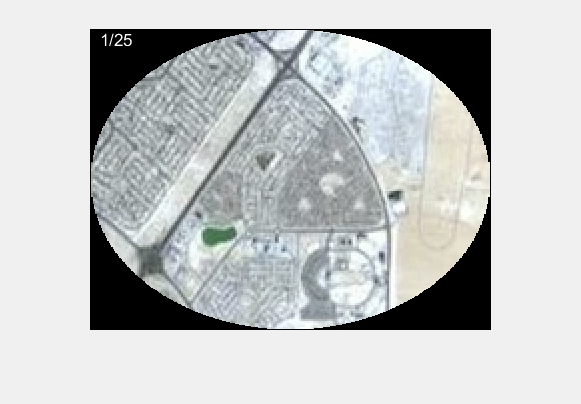

clc
clear all
close all

letter = "B";
directory = "Test Images/Snipped/"+letter+"/";
imagefiles = dir(directory);      
nfiles = length(imagefiles);    % Number of files found

% figure()
counter=1;
for ii=1:nfiles
   currentfilename = imagefiles(ii).name;
   if currentfilename(1)==letter
       currentimage = imread(directory+currentfilename);
       images{counter} = currentimage;
       [~,imageNames{counter},~] = fileparts(currentfilename);
       counter=counter+1;
   end
   % subplot(nfiles-3, 1, ii - 3);
   % imshow(images{ii - 3});
end

neworder = randperm(length(images));
for i=1:length(images)
    images2{i} = images{neworder(i)};
end
images = images2;

% images{1} = imread("Test Images/Snipped/A/A4.jpg");
% images{2} = imread("Test Images/Snipped/A/A7.jpg");
% images{3} = imread("Test Images/Snipped/A/A15.jpg");
% images{4} = imread("Test Images/Snipped/A/A12.jpg");
% images{5} = imread("Test Images/Snipped/A/A18.jpg");

% images{1} = imread("leftoriginal.png")
% images{2} = imread("leftleft.png")

% % right = imread("leftshifted.png");
% figure()
% imshow(images{1})
% imshow(images{2})

fig = figure;
set(gcf,'Visible','on');

out = images{1};
outcount = 1;
length_images = length(images);
thresh = 0.01;
speedthresh = 0.01;
speedthresh_trip=false;
valid_thresh_og = 1;
valid_thresh = valid_thresh_og;
stitched = zeros(length(images),1);
stitched(1)=1;
length(images);

pltanim(out,stitched);


end_early = false;
default_points = 0.5;
points=default_points;
finished = false;
while ~finished
    confidences = zeros(length(stitched),4);
    speedthresh_trip=false;
    for i=1:length(stitched)
        if stitched(i)==0
            if i<=length(images)
                image = images{i};
            else
                image = outputs{i-length(images)};
            end
            [final_slope, final_length, final_delta_x, final_delta_y, final_confidence] = custom_sift(out, image, 8, points, true);
            confidences(i,:)=[final_confidence,final_delta_x,final_delta_y, i];
            if confidences(i,1)>=speedthresh
                [out, valid] = merge_images(out, image, round(-confidences(i,2)), round(-confidences(i,3)),valid_thresh/1.5, true);
                if valid
                    disp(confidences(i,1))
                    speedthresh_trip=true;
                    stitched(i)=1;
                    % points=max(default_points,points-0.5);
                    pltanim(out,stitched);
                end
            end
        end
    end
    if ~speedthresh_trip
        confidences = sortrows(confidences,1,"descend");
        valid = false;
        for c=1:length(confidences)
            if confidences(c,1)>=thresh
                if confidences(c,4)<=length(images)
                    image = images{confidences(c,4)};
                else
                    image = outputs{confidences(c,4)-length(images)};
                end
                % [v,ind]=max(confidences(:,1));
                % disp(v)
                [out, valid] = merge_images(out, image, round(-confidences(c,2)), round(-confidences(c,3)),valid_thresh, true);
                % imwrite(out, "Output/"+letter+"/Run3_Stitch"+sum(stitched)+"_Conf"+round(v*10000)+".png");
                if valid
                    disp(confidences(c,1))
                    stitched(confidences(c,4))=1;
                    % points=max(default_points,points-0.5);
                    pltanim(out,stitched);
                    break
                end
            end
        end
        if ~valid
            % points=points+0.5
            % if points>=1
                outputs{outcount} = out;
                outcount = outcount+1;
                idx = find(stitched==0,1,"first");
                if idx<=length(images)
                    image = images{idx};
                else
                    image = outputs{idx-length(images)};
                end
                out = image;
                points = default_points;
                stitched(idx)=1;
                stitched = [stitched;0];
                pltanim(out,stitched);
                if all(stitched(1:length_images))
                    thresh = thresh/2
                    valid_thresh = valid_thresh+1
                    points = min(3,valid_thresh/4)
                    length_images = length(stitched);
                    % if valid_thresh>7
                    %     thresh=thresh/2
                    % end
                end
                % finished=true;
                % end_early=true;
            % end
        end
    end
    if all(stitched) | valid_thresh>12
        break
    end
end

ans =     0.9802
    0.9796
    0.9794


    0.0221



ans =      0
     0
     0


    0.0369



ans =     0.9579
    0.9583
    0.9619


    0.1273



ans =     0.7732
    0.7721
    0.7786


    0.1635



ans =     0.7904
    0.7911
    0.7921


    0.0267



ans =     0.8496
    0.8497
    0.8516


    0.0323



ans =     0.9549
    0.9778
    0.9879


    0.0108



ans =     0.8812
    0.8844
    0.8871


    0.0591



ans =     0.9147
    0.9136
    0.9156


    0.0179



ans =     0.0645
    0.0612
    0.0707


    0.0798



ans =     0.0168
    0.0146
    0.0173


    0.0174



thresh = 0.0050

valid_thresh = 2

points = 0.5000

ans =     0.4556
    0.9208
    0.8650


    0.0065



ans =     0.9118
    0.9131
    0.9162


    0.0144



ans =     0.7296
    0.7302
    0.7326


    0.0887



ans =     0.5580
    0.5566
    0.5592


    0.0455



ans =     0.6516
    0.6506
    0.6487


    0.0419



ans =     0.4831
    0.4827
    0.4837


    0.0123



ans =     0.2746
    0.2745
    0.2742


    0.0291



ans =     0.6901
    0.6899
    0.6886


    0.0291



ans =     0.8283
    0.8294
    0.8323


    0.0186



thresh = 0.0025

valid_thresh = 3

points = 0.7500

ans =     0.8591
    0.8591
    0.8577


    0.0716



thresh = 0.0013

valid_thresh = 4

points = 1

thresh = 6.2500e-04

valid_thresh = 5

points = 1.2500

ans =     0.1426
    0.1427
    0.1426


    0.0107



ans =     0.0792
    0.0793
    0.0799


    0.0028



thresh = 3.1250e-04

valid_thresh = 6

points = 1.5000

thresh = 1.5625e-04

valid_thresh = 7

points = 1.7500

thresh = 7.8125e-05

valid_thresh = 8

points = 2

thresh = 3.9063e-05

valid_thresh = 9

points = 2.2500

sum(stitched)
% imageNames(~stitched)
pltanim(out,stitched);
text(10,40,"Done!","Color",[1,1,1]);
imwrite(out, "Output/"+letter+"/"+rand()+".png");

function [] = pltanim(out, stitched)
        imshow(out);
        text(10,10,""+sum(stitched)+"/"+length(stitched),"Color",[1,1,1]);
        drawnow();
end